% close(1);

R = 0.01% Pinion gear effective radius

R = 0.0100

J = 1e-4% Motor and pinion moment of inertia

J = 1.0000e-04

m = 4*.343% Mass of rack and plunger

m = 1.3720

b = 0% Rotational damping coefficient (includes back emf)

b = 0

c = 1% Linear damping coefficient (includes friction and damping from chest compressions)

c = 1

k = 1% Spring constant of chest

k = 1


T = 1e-3; % Sampling rate of slowest sensor

s = tf('s');

tau_FOC = 0.00016

tau_FOC = 1.6000e-04


w_c = 50 % rad/s

w_c = 50

phi_m = 45 % deg

phi_m = 45

phi_lag = 10 % deg

phi_lag = 10


K_i = w_c/tand(90 - phi_lag)

K_i = 8.8163

alpha = (1 + sind(phi_m + phi_lag))/(1 - sind(phi_m + phi_lag))

alpha = 10.0590

tau = 1/(w_c*sqrt(alpha))

tau = 0.0063


% Full plant, used to size controller gain
plant = (1/(tau_FOC*s + 1))*(R/((J + m*R^2)*s^2 + (b + c*R)*s + k*R^2));

lead_tf = (alpha*tau*s + 1)/(tau*s + 1);
lag_tf = 1 + K_i/s;

K_p = 1/abs(freqresp(plant*lead_tf*lag_tf, w_c))

K_p = 24.0833


controller_tf = K_p*lead_tf*lag_tf;
L = controller_tf*lag_tf*plant;
% Generate discrete TF


lead_discrete = c2d(lead_tf, T, 'matched');
lag_discrete = c2d(lag_tf, T, 'Tustin');
leadlag_discrete = lead_discrete*lag_discrete;
gain_discrete = abs(freqresp(K_p*lag_tf*lead_tf, .01))/abs(freqresp(leadlag_discrete, .01));

discrete_tf = leadlag_discrete*gain_discrete


discrete_tf =
 
  226.8 z^2 - 448 z + 221.3
  -------------------------
   z^2 - 1.853 z + 0.8534
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


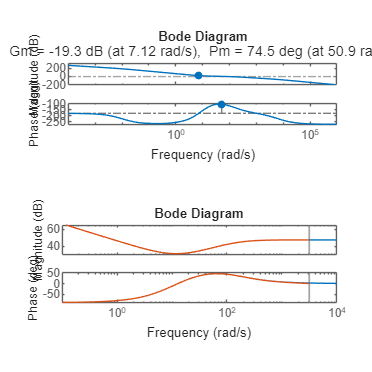

[num_discrete, denom_discrete] = tfdata(discrete_tf);
num_discrete = num_discrete{1};
denom_discrete = denom_discrete{1};

figure(1);
subplot(2, 1, 1)
margin(L)
subplot(2, 1, 2)
bode(controller_tf)
hold on;
bode(discrete_tf)
improvePlot